Telecommunications Systems 2 Assignment 2024

Problem 2

clear

16-PAM - 16-QAM

SNR = 0:0.1:24

SNR =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


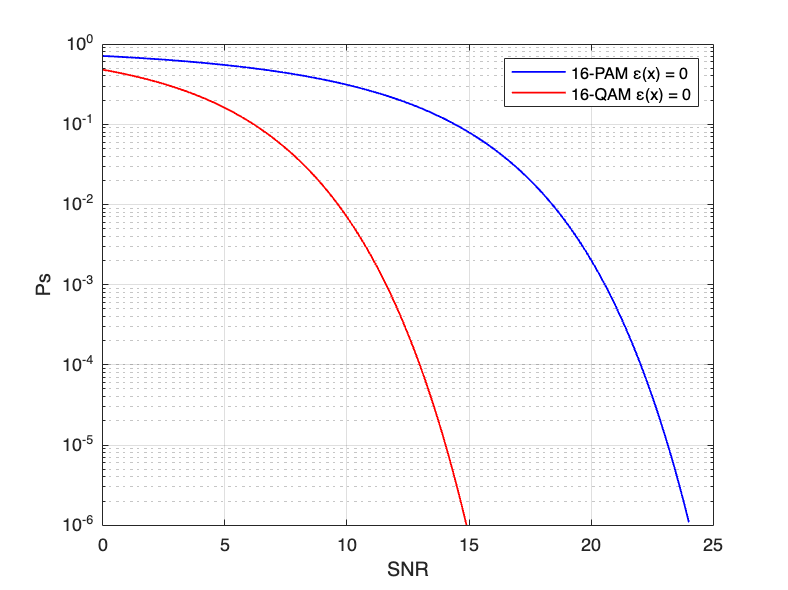

M = 16;
k = log2(M);
N = 4;
n = M/N;
SNR_no_dB = 10.^(SNR/10);

% PAM
Ps_pam = (2*(M - 1) / M) .* qfunc(sqrt((6*k*10.^(SNR/10)) / (M.^2 - 1)));

% QAM
Ps_sqrtM = 2*(1 - sqrt(M) / M) .* qfunc(sqrt((3*k*(10.^(SNR/10))) / (M -1)));
Ps_qam = 1 - (1 - Ps_sqrtM).^2;

figure
semilogy(SNR, Ps_pam, "color", "blue", "LineWidth", 1)
hold on;
semilogy(SNR, Ps_qam, "color", "red", "LineWidth", 1)
hold off;
xlabel("SNR")
ylabel("Ps")
ylim([1e-6 1e0])
legend("16-PAM ε(x) = 0", "16-QAM ε(x) = 0")
grid on